clc,clear,close all;
warning off

**Input image**

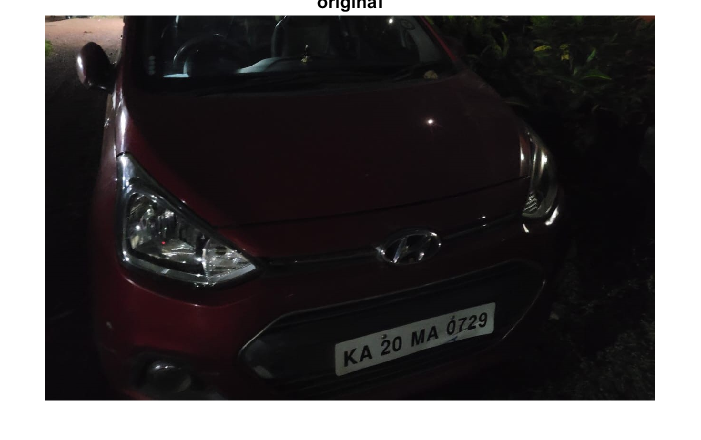

original = imread("pictures\2.jpg");
figure(), imshow(original), title('original')

**Pre-processing**

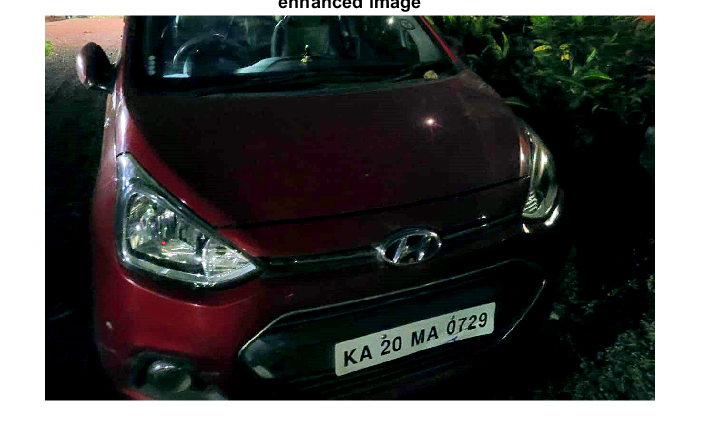

%image enhancement for low light conditions
I = original;
I = imcomplement(I);
I = imreducehaze(I);
enhanced = imcomplement(I);
figure(), imshow(enhanced), title('enhanced image')

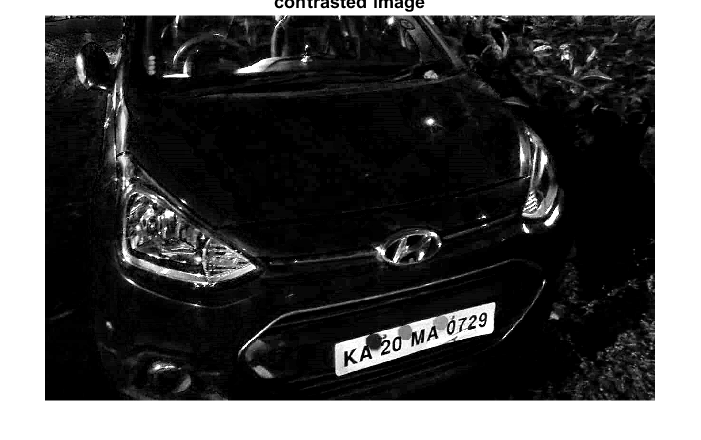


%Converting the image to grayscale
g = rgb2gray(enhanced);

%Top hat filtering the image to seperate the number plate
se = strel('disk',15);
filtered = imtophat(g, se);
contrasted = imadjust(filtered);
figure(), imshow(contrasted), title('contrasted image')

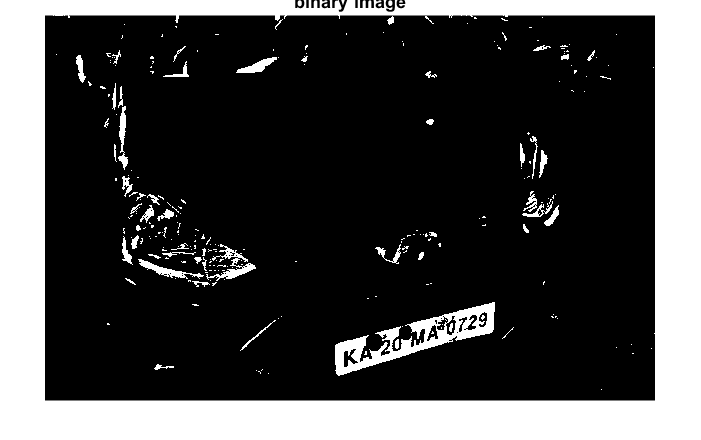


%Binarizing the image
bin = im2bw(contrasted,0.6);
figure(), imshow(bin), title('binary image')

**License plate localisation**

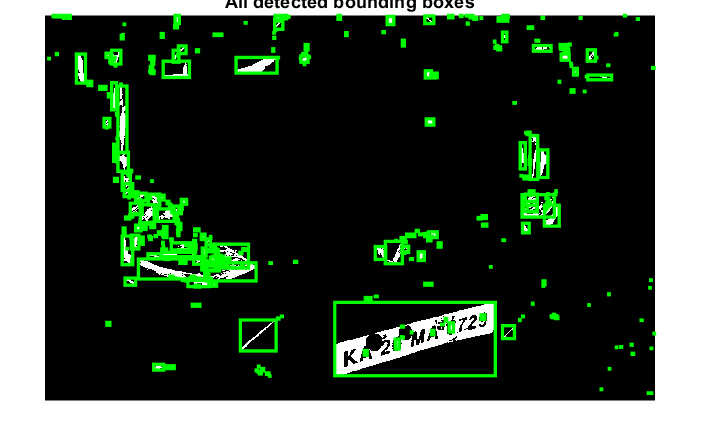

Iprops=regionprops(bin,'BoundingBox','Area');
area = Iprops.Area;
count = numel(Iprops);
maxa= area;
boundingBox = Iprops.BoundingBox;

figure(), imshow(bin), title('All detected bounding boxes');
[L N]=bwlabel(bin); %Label connected components
boxes=regionprops(L,'BoundingBox');
hold on

%%Plot Bounding Boxes
for n=1:size(boxes,1)
      rectangle('Position',boxes(n).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

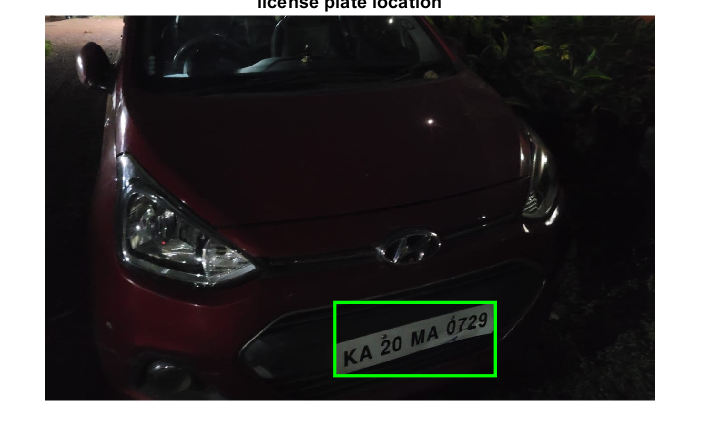


for i=1:count
   if maxa<Iprops(i).Area 
       maxa=Iprops(i).Area;
       boundingBox=Iprops(i).BoundingBox;
   end
end    
numPlate = imcrop(enhanced, boundingBox);%crop the number plate area
numP = rgb2gray(numPlate);
numP = imbinarize(numP);

figure()
imshow(original);
rectangle('Position',boundingBox,'EdgeColor','g','LineWidth',2)
title('license plate location')

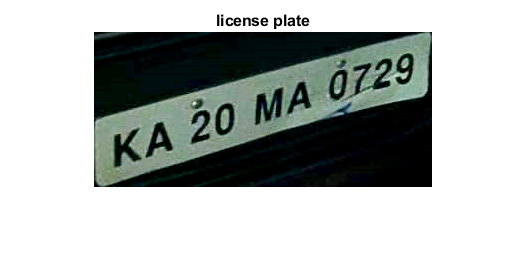


figure()
imshow(numPlate);

title('license plate')

**Text recognition using OCR**

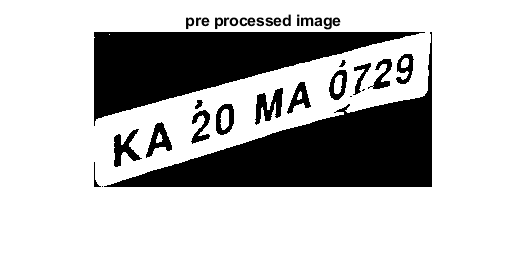

%Image pre-processing to imrove results
th = imtophat(numPlate,strel('disk',20));
eroded = imerode(th, strel('line',5,0));
Iclean = imreconstruct(eroded, th);
Iclean = rgb2gray(Iclean);
bin2 = imbinarize(Iclean);
figure(), imshow(numP), title('pre processed image');

results = ocr(numP);
number = strip(results.Text);
number = number(isstrprop(number,"alphanum"));

**Deskewing**

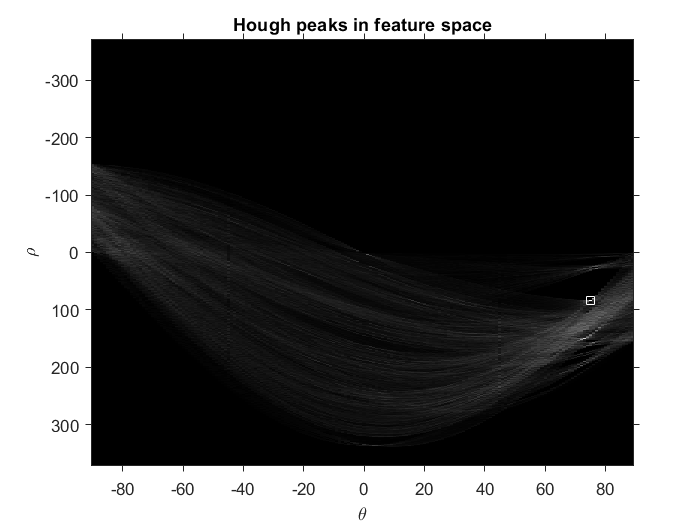

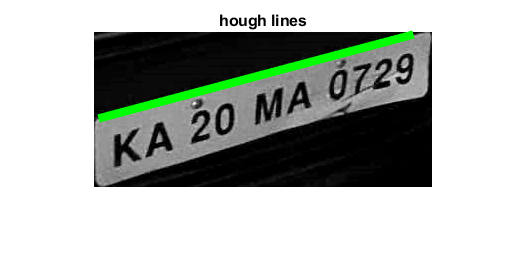

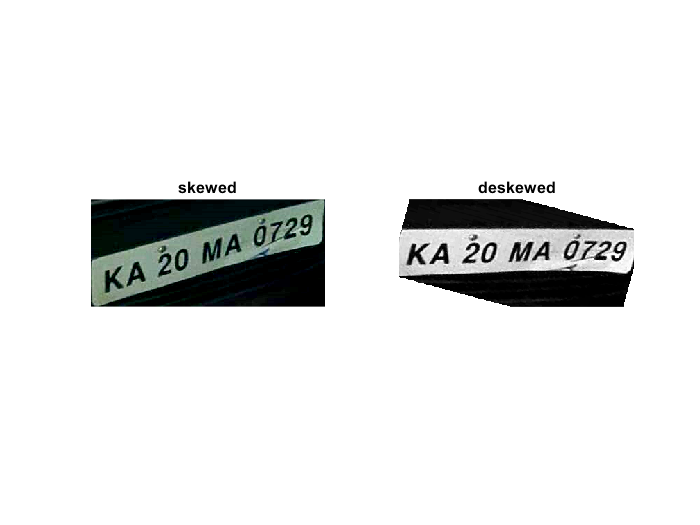

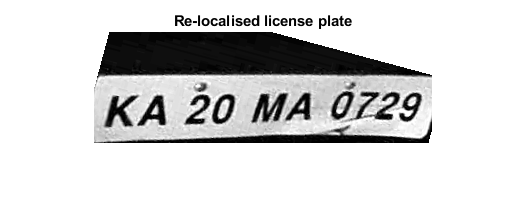

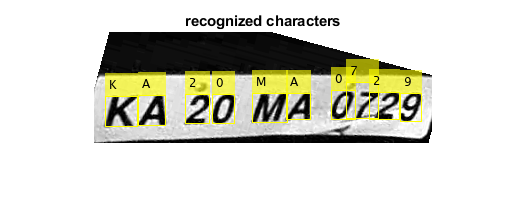

if length(number)<1
    sam=numPlate;
    gray = rgb2gray(numPlate);
    m=imadjust(gray);
    [r, c]=size(gray);
    BW = edge(m,'canny');
    [H,T,R] = hough(BW);
    
    P  = houghpeaks(H,1,'threshold',ceil(0.9*max(H(:))));
    lines = houghlines(BW,T,R,P,'FillGap',0.8*c,'MinLength',40);
    
    figure()
    imshow(H,[],'XData',T,'YData',R,'InitialMagnification','fit'), title('Hough peaks in feature space');
    xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;
    x = T(P(:,2)); y = R(P(:,1));
    plot(x,y,'s','color','white');

    figure(), imshow(gray), title('hough lines'), hold on
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:,1),xy(:,2),'LineWidth',5,'Color','green');
    end
    figure();
    if(lines.theta<0)
        g=imrotate_white(m,(90-abs(lines.theta)));
    else
        g=(imrotate_white(m,lines.theta-90));
    end
    subplot(1,2,1),imshow(sam);
    title('skewed')
    subplot(1,2,2);imshow(g);
    title('deskewed')
    
    
    %Localizing again after deskewing
    h = imbinarize(g);
    Iprops=regionprops(h,'BoundingBox','Area');
    area = Iprops.Area;
    count = numel(Iprops);
    maxa= area;
    boundingBox = Iprops.BoundingBox;

    for i=1:count
        if maxa<Iprops(i).Area 
            maxa=Iprops(i).Area;
            boundingBox=Iprops(i).BoundingBox;
        end
    end    
    j = imcrop(g, boundingBox);%crop the number plate area
    figure(),imshow(j),
    title('Re-localised license plate')
    
    %OCR
    results = ocr(j);
    number = strip(results.Text);
    number = number(isstrprop(number,"alphanum"));
    
    regularExpr = '\w';
    bboxes = locateText(results,regularExpr,'UseRegexp',true);
    chars = regexp(results.Text,regularExpr,'match');
    Ichars = insertObjectAnnotation(j,'rectangle',bboxes,chars);
    figure(), imshow(Ichars), title('recognized characters');
else
    regularExpr = '\w';
    bboxes = locateText(results,regularExpr,'UseRegexp',true);
    chars = regexp(results.Text,regularExpr,'match');
    Ichars = insertObjectAnnotation(numPlate,'rectangle',bboxes,chars);
    figure()
    imshow(Ichars);
    title('recognized characters')
end

number

number = 'KA20MA0729'

**Vehicle Entry Authentication**

t = readtable('data.csv');%read database

check = 0;
for i=1:length(t.Numberplates)
    if(strfind(number,t.Numberplates(i))~=0)
        check=1;
    end
end

if check == 1
    disp("Vehicle is allowed to enter")
else
    disp("Vehicle is not allowed to enter")
end

Vehicle is allowed to enter


function rotated_image = imrotate_white(image, rot_angle_degree)
    RA = imref2d(size(image));    
    tform = affine2d([cosd(rot_angle_degree)    -sind(rot_angle_degree)     0; ...
                      sind(rot_angle_degree)     cosd(rot_angle_degree)     0; ...
                      0                          0                          1]);
      Rout = images.spatialref.internal.applyGeometricTransformToSpatialRef(RA,tform);
      Rout.ImageSize = RA.ImageSize;
      xTrans = mean(Rout.XWorldLimits) - mean(RA.XWorldLimits);
      yTrans = mean(Rout.YWorldLimits) - mean(RA.YWorldLimits);
      Rout.XWorldLimits = RA.XWorldLimits+xTrans;
      Rout.YWorldLimits = RA.YWorldLimits+yTrans;
      rotated_image = imwarp(image, tform, 'OutputView', Rout, 'interp', 'cubic', 'fillvalues', 255);
end